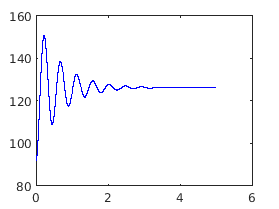

clc; clear all; close all;
m1 = 284; % kg
m2 = 260; % kg
g = 9.81; % m/s^2
k1 = 260000; % N/m
L01 = 115/1000; % m
b1 = 4000; % N*s/m
theta = deg2rad(51); % rad
x1 = 92/1000; % m
x1Dot = 0; % m/s

simTime = 5; % s
t = 0; % s
dt = 10^-5; % s
idx = 1; % Counter

while(t <= simTime)
    % Calculations

    % F = ma
    delta1 = x1-L01;
    delta1Dot = x1Dot;

    Fk1 = delta1 * k1;
    Fb1 = delta1Dot * b1;
    Fg1 = m1*g*sin(theta);
    sumF = -Fg1-Fk1-Fb1+2*m2*g;
    x1DotDot = sumF/(m1+4*m2);

    % Logging
    t_plt(idx) = t;
    x1_plt(idx) = x1;
    x1Dot_plt(idx) = x1Dot;

    % Time integrate
    x1Dot = x1Dot + x1DotDot*dt;
    x1 = x1 + x1Dot*dt;

    % Update variables
    t = t + dt;
    idx = idx + 1;
end

plot(t_plt, x1_plt*1000, 'b')

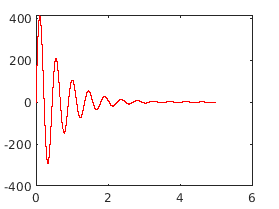

plot(t_plt, x1Dot_plt*1000, 'r')


abs(max(x1Dot_plt))*1000

ans =           410.074181496249


abs(min(x1Dot_plt))*1000

ans =           291.693066365116
